# สัญญาณและระบบแบบเวลาไม่ต่อเนื่อง (Discrete-time Signal & System)

# ตอนที่ 5 : การทำให้เป็นเวลาไม่ต่อเนื่อง (Discretization)

ระบบทางกายภาพส่วนใหญ่เป็นระบบแบบเวลาต่อเนื่อง เราได้ทำการจำลอง วิเคราะห์ และออกแบบระบบที่มีเวลาแบบต่อเนื่อง แต่**ในโลกความเป็นจริง แพลตฟอร์มที่ใช้ในการคำนวณนั้นไม่สามารถทำให้เป็นแบบเวลาต่อเนื่องได้ เราจึงต้องทำการประมาณให้เป็นเวลาไม่ต่อเนื่อง (discretization) **

หากเราออกแบบระบบควบคุมแบบ LTI ที่อยู่ในโดเมนของเวลาดังต่อไปนี้


$$\begin{array}{l}
\frac{\mathrm{d}}{\mathrm{d}\;t}\left(i\left(t\right)\right)=e\left(t\right)\\
c\left(t\right)=K_p \cdot e\left(t\right)+K_i \cdot i\left(t\right)
\end{array}$$


โดยที่ 

$e$ คืออินพุต 

$c$ คือเอ้าท์พุต 

$K_p$ กับ $K_i$ คือค่าคงที่

เราสามารถประมาณระบบนี้ได้โดยการประมาณอนุพันธ์ของ $i$ 

**เราจะกำหนด **$\Delta \;t$** เป็นระยะเวลาในแต่ละช่วงการคำนวณ ยิ่งช่วงการคำนวณน้อย การคำนวณก็จะละเอียดและแม่นยำมากขึ้น แต่การคำนวณที่มากขึ้นจะใช้พลังในการคำนวณมากขึ้นด้วยเช่นกัน**

วิธีการแรกที่สามารถใช้ประมาณอนุพันธ์คือการหาผลต่างข้างหน้า (Forward Difference/ Euler's method) ซึ่งเขียนได้ดังต่อไปนี้


$$\frac{\mathrm{d}}{\mathrm{d}\;t}\left(i\left(t_n \right)\right)\approx \frac{i\left(t_{n+1} \right)-i\left(t_n \right)}{\Delta t}=\frac{i\left\lbrack n+1\right\rbrack -i\left\lbrack n\right\rbrack }{\Delta t}$$


วิธีการที่สองคือการหาผลต่างข้างหลัง (Backward Difference) ซึ่งเขียนได้ดังต่อไปนี้


$$\frac{\mathrm{d}}{\mathrm{d}\;t}\left(i\left(t_n \right)\right)\approx \frac{i\left(t_n \right)-i\left(t_{n-1} \right)}{\Delta t}=\frac{i\left\lbrack n\right\rbrack -i\left\lbrack n-1\right\rbrack }{\Delta t}$$


วิธีการสุดท้ายคือการหาผลต่างกึ่งกลาง (Central Difference) ซึ่งเขียนได้ดังต่อไปนี้


$$\frac{\mathrm{d}}{\mathrm{d}\;t}\left(i\left(t_n \right)\right)\approx \frac{i\left\lbrack n+1\right\rbrack -i\left\lbrack n-1\right\rbrack }{\Delta t}$$


หากเราใช้วิธีผลต่างข้างหน้า เราจะสามารถประมาณระบบควบคุมได้ดังต่อไปนี้


$$\begin{array}{l}
i\left\lbrack n+1\right\rbrack =i\left\lbrack n\right\rbrack +\Delta t\cdot e\left\lbrack n\right\rbrack \\
c\left\lbrack n\right\rbrack =K_p \cdot e\left\lbrack n\right\rbrack +K_i \cdot i\left\lbrack n\right\rbrack 
\end{array}$$


นอกจากการประมาณในโดเมนของเวลา เราสามารถประมาณฟังก์ชันถ่ายโอนในโดเมนของลาปลาซได้เช่นกัน ก**ารทำให้เป็นเวลาไม่ต่อเนื่องในโดเมนของลาปลาซคือการแปลงฟังก์ชันถ่ายโอนจากโดเมนของลาปลาซให้เป็นโดเมนของ Z** ซึ่งมีวิธีหลักทั้ง 3 วิธีดังนี้

วิธีแรกในการประมาณคือ การหาผลต่างข้างหน้า ซึ่งเราจะประมาณตัวแปร $s$ ให้เป็นค่าดังต่อไปนี้ 


$$s\approx \frac{z-1}{\Delta t}$$


วิธีที่สองในการประเมาณคือ การหาผลต่างข้างหลัง ซึ่งเขียนความสัมพันธ์ได้ดังต่อไปนี้


$$s\approx \frac{1-z^{-1} }{\Delta t}$$


วิธีทีสุดท้ายคือ การแปลงแบบสองเส้น (bilinear transformation/Tustin' method) หาผลต่างข้างหลัง ซึ่งเขียนความสัมพันธ์ได้ดังต่อไปนี้


$$s\approx \frac{2}{\Delta t}\left(\frac{1-z^{-1} }{1+z^{-1} }\right)$$


## ตัวอย่างที่ 1: ตัวกรอง low-pass อันดับที่หนึ่ง

กำหนดให้ตัวกรองถูกออกแบบดังต่อไปนี้


$$G\left(s\right)=\frac{Y\left(s\right)}{U\left(s\right)}=\frac{\omega_c }{s+\omega_c }$$


เราประมาณโดยใช้วิธีแปลงแบบสองเส้น $s\approx \frac{z-1}{\Delta t}$ ซึ่งทำให้เราได้ฟังก์ชันถ่ายโอนในโดเมนของ Z


$$\begin{array}{l}
G\left(z\right)=\frac{\omega_c }{\left(\frac{z-1}{\Delta t}\right)+\omega_c }\\
G\left(z\right)=\frac{\omega_c \Delta t}{z+\left(\omega_c \Delta t-1\right)}\\
G\left(z\right)=\frac{Y\left(z\right)}{U\left(z\right)}=\frac{\omega_c \Delta t}{z+\left(\omega_c \Delta t-1\right)}
\end{array}$$


เมื่อเราได้ฟังก์ชันถ่ายโอนในโดเมนของ Z เราสามารถแปลงฟังก์ชันถ่ายโอนกลับไปยังโดเมนของเวลาแบบไม่ต่อเนื่องได้ 

เนื่องจากระบบเป็นอันดับที่หนึ่ง เราสามารถเขียนตัวกรองของเราในรูปแบบปริภูมิสถานะดังต่อไปนี้


$$\begin{array}{l}
x\left\lbrack n+1\right\rbrack =a\cdot x\left\lbrack n\right\rbrack +b\cdot u\left\lbrack n\right\rbrack \\
y\left\lbrack n\right\rbrack =c\cdot x\left\lbrack n\right\rbrack +d\cdot u\left\lbrack n\right\rbrack 
\end{array}$$


โดยที่

$x\in \Re$ เป้นสถานะ

$u\in \Re$ เป็นสัญญาณอินพุตที่โดนกรอง

$y\in \Re$ เป็นสัญญาณเอ้าท์พุตที่ได้มาจากการกรอง

ส่วน $a$, $b$, $c$, และ $d$ เป็นค่าคงที่ที่ต้องหา หรืออีกความหมายหนึ่งก็คือ เราจำเป็นต้องหาว่าระบบแบบเวลาไม่ต่อเนื่องใดที่ทำให้ฟังก์ชันถ่ายโอนมีลักษณะเดียวกันกับตัวกรองที่ออกแบบมา

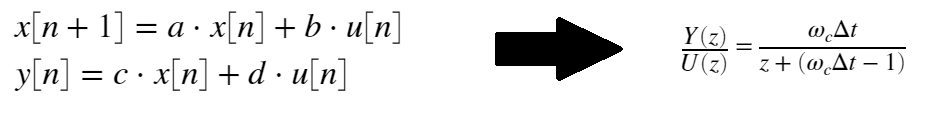

เราจะสามารถแก้โจทย์นี้ได้หลายวิธี โดยปกติการคำนวณนี้สามารถใช้การแปลง Z ผกผัน (Inverse Z-transform) แต่การทำในรูปแบบนั้นอาจจะทำให้เขียนในรูปปริภูมิสถานะได้ลำบาก เราจึงใช้การแปลง Z จากปริภูมิสถานะไปเป็นฟังก์ชันถ่ายโอนแทนซึ่งเราจะสามารถเขียนเป็นสมการได้ดังต่อไปนี้


$$\begin{array}{l}
\mathit{\mathbf{Z}}\left\lbrace x\left\lbrack n+1\right\rbrack \right\rbrace =\mathit{\mathbf{Z}}\left\lbrace a\cdot x\left\lbrack n\right\rbrack +b\cdot u\left\lbrack n\right\rbrack \right\rbrace \\
z^1 \cdot X\left(z\right)=a\cdot X\left(z\right)+b\cdot U\left(z\right)\\
X\left(z\right)=\frac{b}{z-a}\cdot U\left(z\right)\\
\mathit{\mathbf{Z}}\left\lbrace y\left\lbrack n\right\rbrack \right\rbrace =\mathit{\mathbf{Z}}\left\lbrace c\cdot x\left\lbrack n\right\rbrack +d\cdot u\left\lbrack n\right\rbrack \right\rbrace \\
Y\left(z\right)=c\cdot X\left(z\right)+d\cdot U\left(z\right)=\left(\frac{b\cdot c}{z-a}+d\right)\cdot U\left(z\right)
\end{array}$$


จากโจทย์การแปลง เราได้เปลี่ยนรูปให้การเป็นโจทย์การหาสัมประสิทธิ์ของเศษส่วนดังต่อไปนี้


$$\begin{array}{l}
\frac{Y\left(z\right)}{U\left(z\right)}=\frac{b\cdot c}{z-a}+d=\frac{\omega_c \Delta t}{z+\left(\omega_c \Delta t-1\right)}\\
a=1-\omega_c \Delta t\\
b=\omega_c \Delta t\\
c=1\\
d=0
\end{array}$$


เราสามารถกำหนดให้


$$\begin{array}{l}
a=1-\omega_c \Delta t\\
b=\omega_c \Delta t\\
c=1\\
d=0
\end{array}$$


ดังนั้นเราจะได้รูปแบบปริภูมิสถานะดังต่อไปนี้


$$\begin{array}{l}
x\left\lbrack n+1\right\rbrack =\left(1-\omega_c \Delta t\right)\cdot x\left\lbrack n\right\rbrack +\left(\omega_c \Delta t\right)\cdot u\left\lbrack n\right\rbrack \\
y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack 
\end{array}$$


ระบบที่ได้เป็นระบบแบบเวลาไม่ต่อเนื่องซึ่งมาจากระบแบบเวลาต่อเนื่องดังต่อไปนี้


$$\begin{array}{l}
\frac{\mathrm{d}}{\mathrm{d}\;t}\left(x\left(t\right)\right)=-\omega_c \cdot x\left(t\right)+\omega_c \cdot u\left(t\right)\\
y\left(t\right)=x\left(t\right)
\end{array}$$


เราจะเทียบระบบแบบเวลาต่อเนื่องกับระบบที่ถูกประมาณให้เวลาไม่ต่อเนื่อง ณ ช่วงการคำนวณที่แตกต่างกันไป

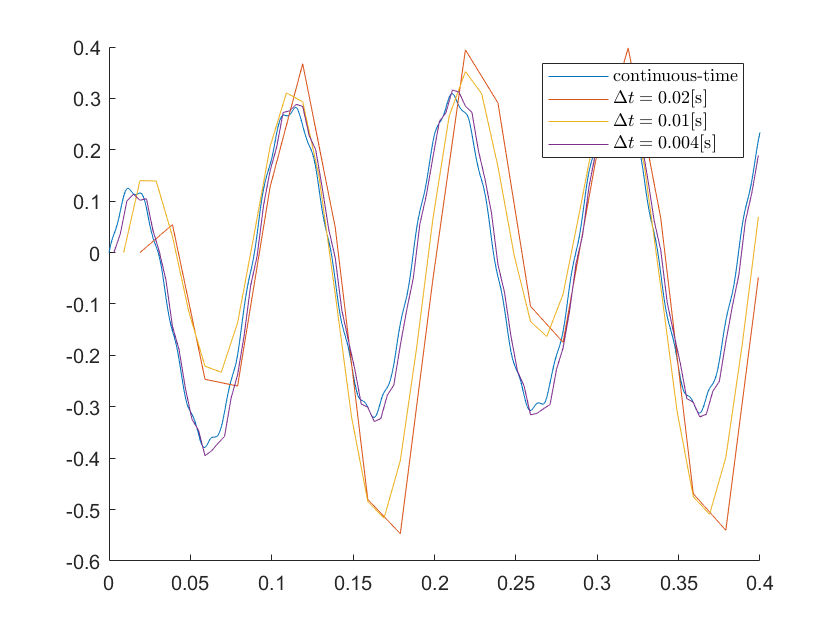

% generate signal with noise
R_in = 1;
R_noise = 0.3;
f_in = 10;
f_noise = 95;
w_in = 2*pi*f_in;
w_noise = 2*pi*f_noise;
phi_in = pi/6;
phi_noise = pi/2;
f = @(t)R_in*cos(w_in*t+phi_in);
w = @(t)R_noise*cos(w_noise*t+phi_noise);

w_c = 20;
t_max = 0.4;
y0 = 0;
[t,y] = ode45(@(t,y)w_c*(-y+f(t)+w(t)),[0:(1/1000):t_max],y0);

clf
ax = axes;
hold(ax,'on')
plot(ax,t,y)

%
time_step = 1/1000;
for f_s = [50 100 250]
    dt = 1/f_s;
    N = 400;
    t_u = [];
    t_y = [];
    u_out = [];
    y_out = [];
    t = 0;
    x = 0;
    for n = 1:N
        u = f(t)+w(t);
        t_u = [t_u;t];
        u_out = [u_out;u];
        if ~mod(n,dt/time_step)
            y = x;
            x = (1-w_c*dt)*x+w_c*dt*u;
            y_out = [y_out;y];
            t_y = [t_y;t];
        end
        t = t+time_step;
    end
    plot(ax,t_y,y_out)
end
legend({'continuous-time','$\Delta t=0.02$[s]','$\Delta t=0.01$[s]','$\Delta t=0.004$[s]'},'Interpreter',"latex")

**เราจะสังเกตได้ว่า ยิ่งช่วงเวลาคำนวณน้อยมากเท่าไหร่ ระบบที่ถูกประมาณจะใกล้เคียงกับระบบแบบเวลาต่อเนื่องมากขึ้นเท่านั้น ดังนั้น การจำกัดช่วงการคำนวณที่คงที่และมีค่าน้อยเป็นส่วนสำคัญในการประยุกต์ใช้ digital filter/controller**